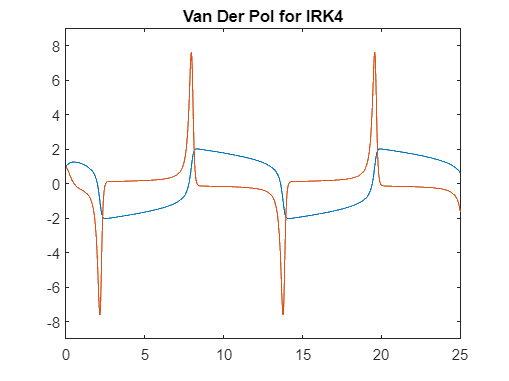

clc;clear all; close all;
%Defining the different symbols here:
syms x y real

%Defining the parameters and converting the symbol to a anonymous function
u=5;
tf=25;
dt=0.01;
N=tf/dt;
f1=y;
f2=((u*((1-x.^2)*y))-x);
ht1=matlabFunction(f1,'Vars',{x,y});
ht2=matlabFunction(f2,'Vars',{x,y});
Plothelp=linspace(0, tf,N)';
toldo=1e-5;
Stages=2;
n=2;

%Here we compute the Implicit RK4:
ButchTIM=[1/2 - sqrt(3)/6, 1/4, 1/4-sqrt(3)/6;1/2 + sqrt(3)/6, 1/4 + sqrt(3)/6, 1/4;0, 1/2, 1/2];
aRK4IM=ButchTIM(1:2,2:3);  
bRK4IM=ButchTIM(3,2:3);
cRK4IM=ButchTIM(1:2,1);
KIM_int=zeros(n*Stages,n*Stages)';
xRK4IM=ones(N,1);
yRK4IM=ones(N,1);
KIM=sym('KIM',[n,Stages],'real');
r1=sym('r1',[1,Stages*n],'real')';
KIM=reshape(KIM,1,Stages*n);

%Here compute the necessary functions for the Newton method, and fill in r1:
for j = 1:Stages
    r1(n*j-(n-1):n*j-(n-1))=KIM(n*j-(n-1))-ht1(x+dt*(aRK4IM(j,1)*KIM(1)+aRK4IM(j,2)*KIM(3)),y+dt*(aRK4IM(j,1)*KIM(2)+aRK4IM(j,2)*KIM(4)));
end

for j = 1:Stages
     r1(n*j-(n-1)+1:n*j-(n-1)+1)=KIM(n*j-(n-1)+1)-ht2(x+dt*(aRK4IM(j,1)*KIM(1)+aRK4IM(j,2)*KIM(3)),y+dt*(aRK4IM(j,1)*KIM(2)+aRK4IM(j,2)*KIM(4)));
end
dr=jacobian(r1',KIM);
Fun_r1=matlabFunction(r1,'Vars',{'KIM1_1','KIM1_2','KIM2_1','KIM2_2','y','x'});
Fun_r2=matlabFunction(dr\r1,'Vars',{'KIM1_1','KIM1_2','KIM2_1','KIM2_2','y','x'});

%Here we compute the Newton iteration:
for i=1:N-1
    HELP_VAR=2;
    while HELP_VAR > 1
        KIM_int=KIM_int-Fun_r2(KIM_int(1),KIM_int(3),KIM_int(2),KIM_int(4),yRK4IM(i),xRK4IM(i));
        if norm(Fun_r1(KIM_int(1),KIM_int(3),KIM_int(2),KIM_int(4),yRK4IM(i),xRK4IM(i)))< toldo
            HELP_VAR=1;
        end     
    end
    
    yRK4IM(i+1)=yRK4IM(i)+dt*((bRK4IM(1)*KIM_int(2))+(bRK4IM(2)*KIM_int(4)));
    xRK4IM(i+1)=xRK4IM(i)+dt*((bRK4IM(1)*KIM_int(1))+(bRK4IM(2)*KIM_int(3)));
end
xRK4IM_y=[xRK4IM yRK4IM];

figure(1)
plot(Plothelp,xRK4IM_y);title('Van Der Pol for IRK4');
xlim([0 25])
ylim([-9 9])